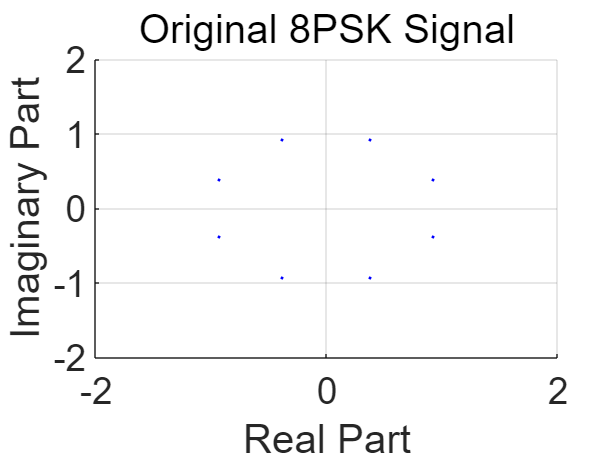

%% 8PSK 신호 처리 및 시각화
% 이 스크립트는 8PSK 변조 신호에 대해 Rayleigh fading과 AWGN을 적용하고,
% 이퀄라이저를 통해 복원된 신호의 성상도를 시각화합니다.

% 기본 설정
numSymbols = 4000; % 심볼 개수
M = 8; % 8PSK
SNR_dB = 10; % 테스트할 SNR 값
fs = 14; % 폰트 크기 설정
markerSize = 4; % 점 크기 설정

% 원본 데이터 생성
data = randi([0 M-1], 1, numSymbols); % 랜덤 데이터 생성
txSignal = pskmod(data, M, pi/M); % 8PSK 변조

% 원본 신호의 성상도
figure;
scatter(real(txSignal), imag(txSignal), markerSize, 'bo', 'filled');
xlim([-2, 2]);
ylim([-2, 2]);
xlabel('Real Part', 'FontSize', fs);
ylabel('Imaginary Part', 'FontSize', fs);
title('Original 8PSK Signal', 'FontSize', fs);
grid on;

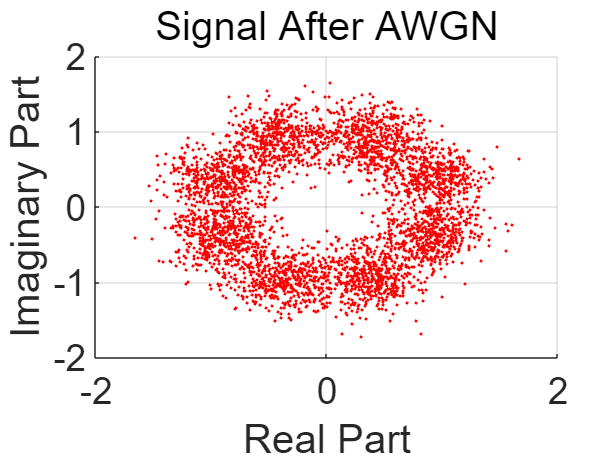


% AWGN 추가
AWGN_signal = sqrt(0.5*10^(-SNR_dB/10)) * (randn(1, length(txSignal)) + 1j * randn(1, length(txSignal))); % 가우시안 잡음
noisySignal = txSignal + AWGN_signal;

% AWGN 추가 후 신호의 성상도
figure;
scatter(real(noisySignal), imag(noisySignal), markerSize, 'ro', 'filled');
xlim([-2, 2]);
ylim([-2, 2]);
xlabel('Real Part', 'FontSize', fs);
ylabel('Imaginary Part', 'FontSize', fs);
title('Signal After AWGN', 'FontSize', fs);
grid on;

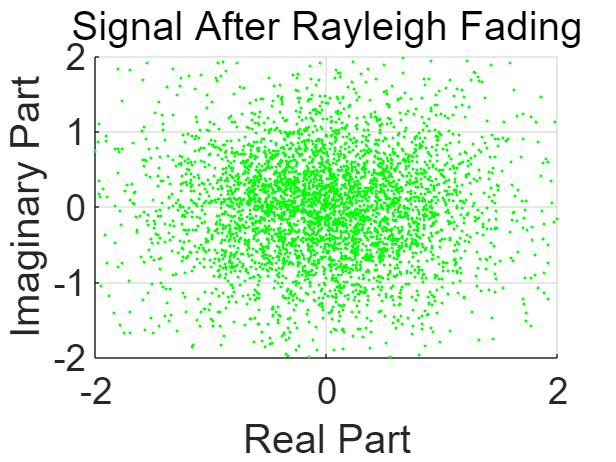


% Rayleigh fading 적용
Fading = sqrt(0.5) * (randn(1, length(txSignal)) + 1j * randn(1, length(txSignal))); % 채널 페이딩
Faded_signal = Fading .* noisySignal; % 페이딩된 신호

% 페이딩된 신호의 성상도
figure;
scatter(real(Faded_signal), imag(Faded_signal), markerSize, 'go', 'filled');
xlim([-2, 2]);
ylim([-2, 2]);
xlabel('Real Part', 'FontSize', fs);
ylabel('Imaginary Part', 'FontSize', fs);
title('Signal After Rayleigh Fading', 'FontSize', fs);
grid on;

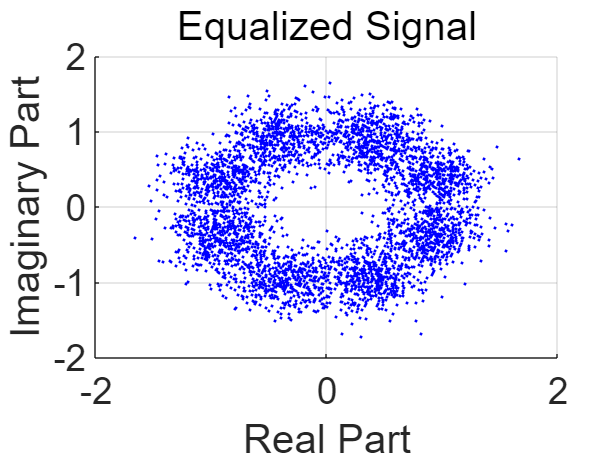


% 이퀄라이저 적용 (채널의 역수로 나누기)
equalized_signal = Faded_signal ./ Fading;

% 이퀄라이징된 신호의 성상도
figure;
scatter(real(equalized_signal), imag(equalized_signal), markerSize, 'bo', 'filled');
xlim([-2, 2]);
ylim([-2, 2]);
xlabel('Real Part', 'FontSize', fs);
ylabel('Imaginary Part', 'FontSize', fs);
title('Equalized Signal', 'FontSize', fs);
grid on;